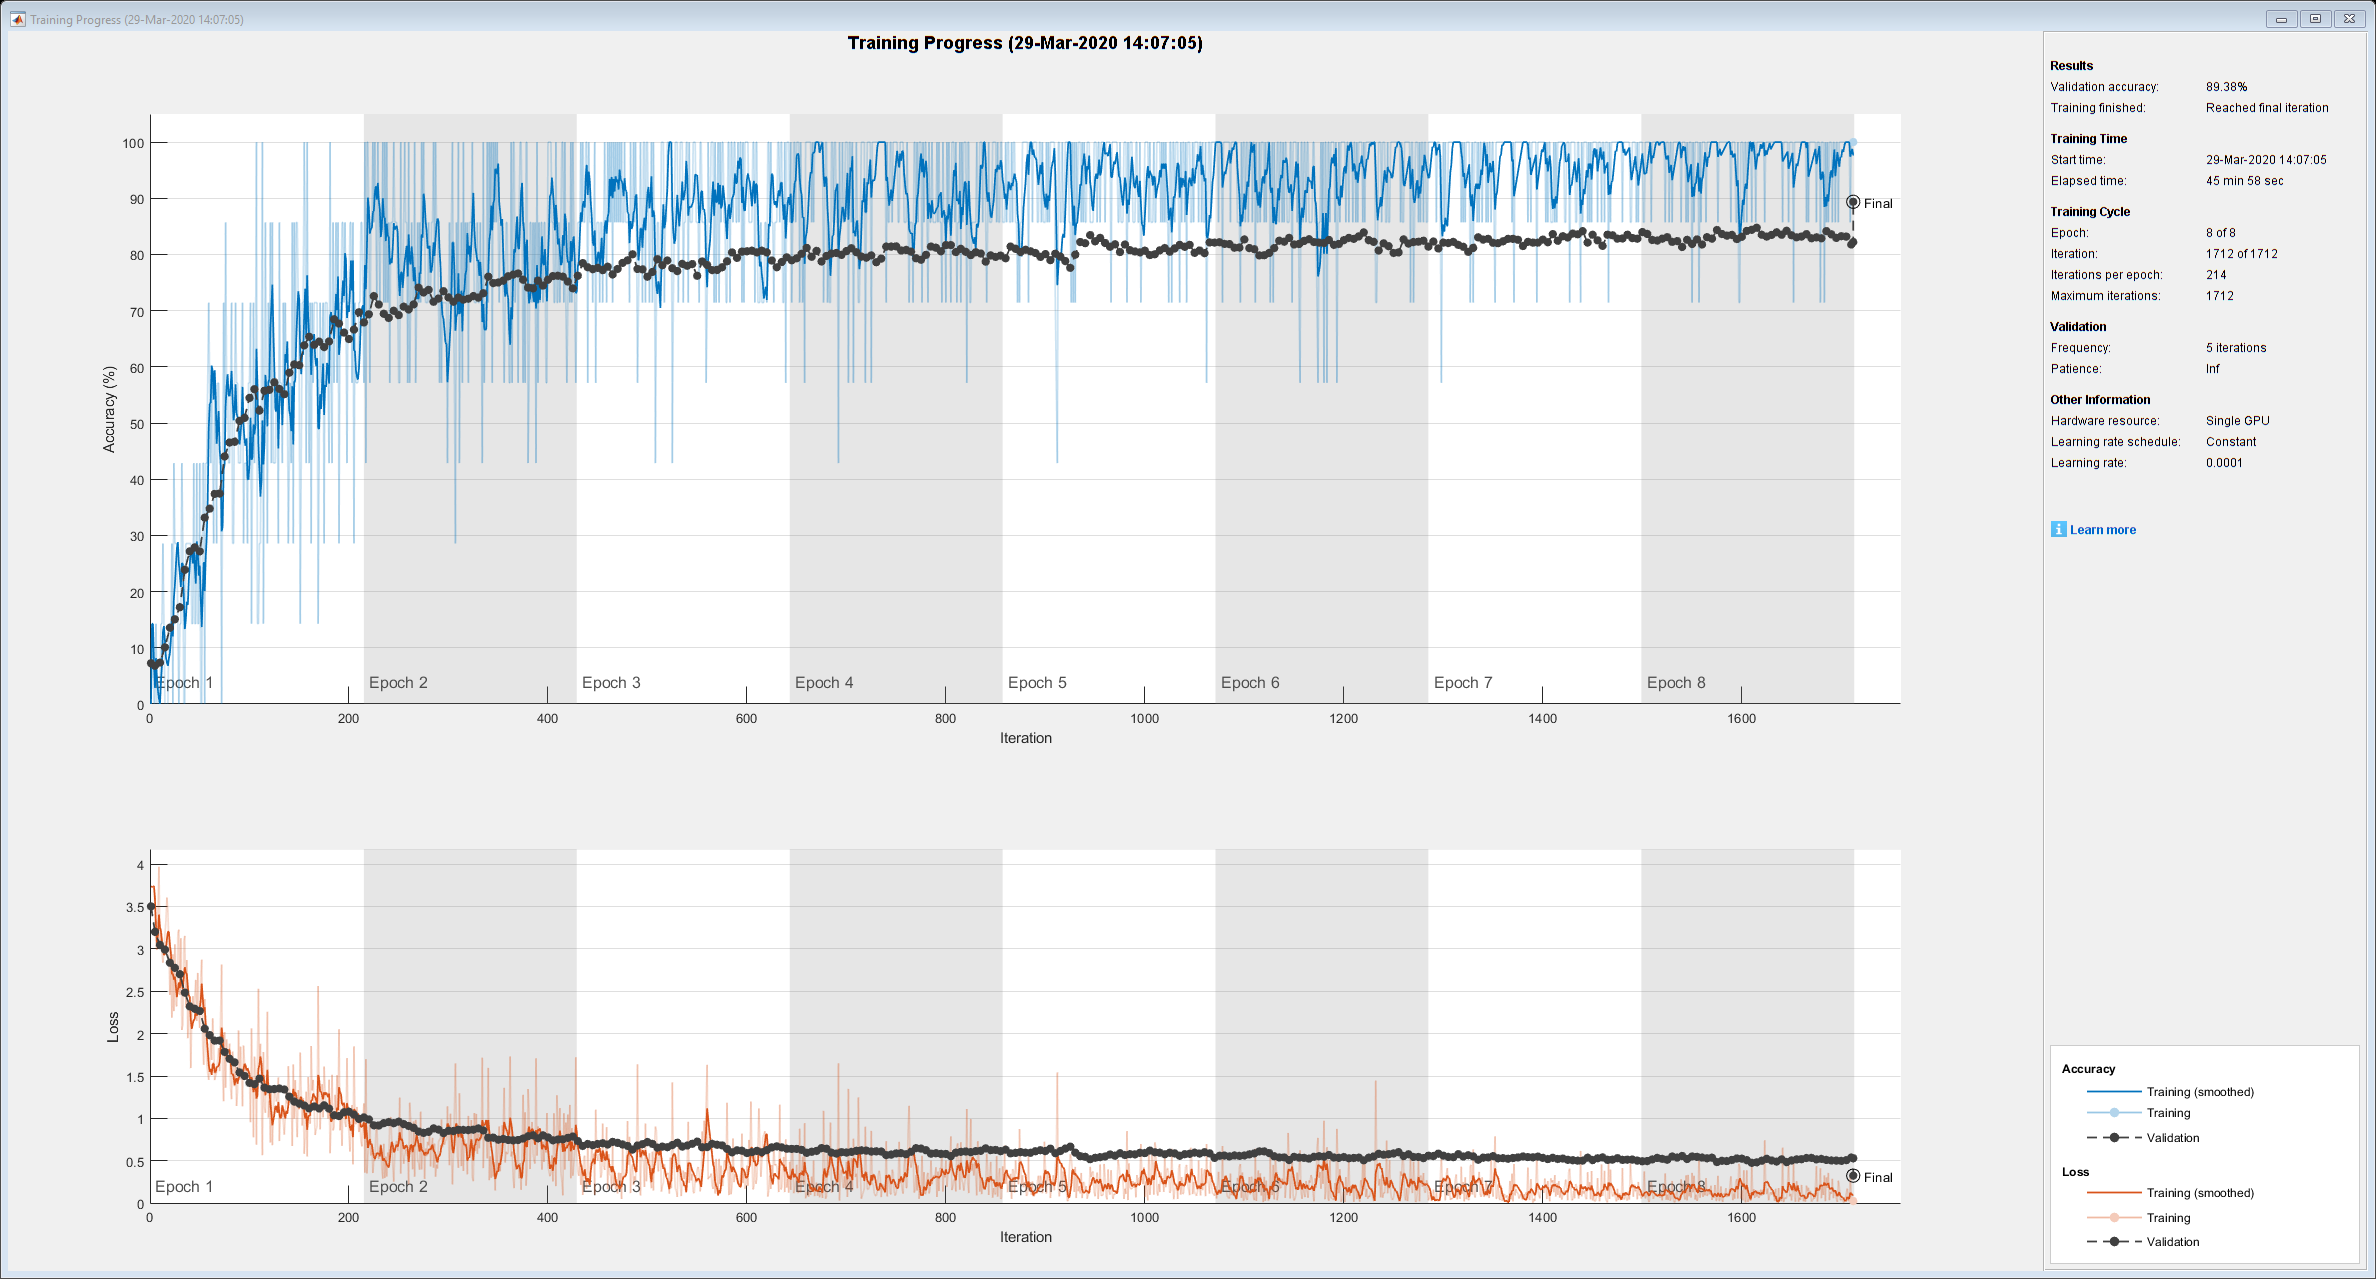

imdsTrain = imageDatastore('sceneData/sceneData/train','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('sceneData/sceneData/test','IncludeSubfolders',true,'LabelSource','foldernames');
net = resnet18;
numClasses = numel(categories(imdsTrain.Labels));
lgraph = layerGraph(net);
newFCLayer = fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newFCLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);
inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,'ColorPreprocessing','gray2rgb');
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest,'ColorPreprocessing','gray2rgb');
options = trainingOptions('sgdm', ...
    'MiniBatchSize',7, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsTest, ...
    'ValidationFrequency',5, ...
    'Verbose',false, ...
    'Plots','training-progress');
trainedNet = trainNetwork(augimdsTrain,lgraph,options);

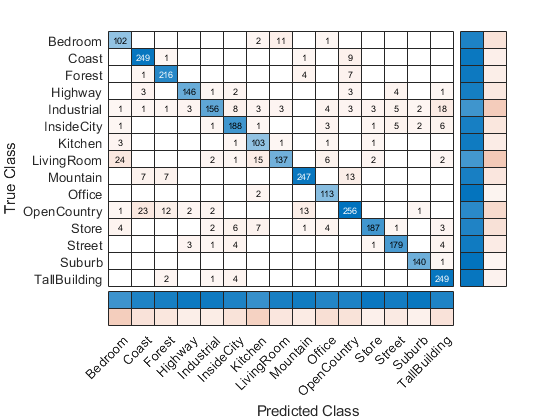

YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;
CList = categories(YTrain);
YPred = classify(trainedNet,augimdsTest);
fscore = zeros(1,length(CList));
for i = 1:length(CList)
    TP = sum((YPred == CList(i)) & (YTest == CList(i)));
    Precision = TP / sum(YPred == CList(i));
    Recall = TP / sum(YTest == CList(i));
    fscore(:,i) = 2*((Precision*Recall)/(Precision+Recall));
end
confusion = confusionchart(YTest,YPred);
confusion.ColumnSummary = 'column-normalized';
confusion.RowSummary = 'row-normalized';

accuracy = mean(YPred == YTest)

accuracy = 0.8938

fscore

fscore =     0.8095    0.9154    0.9251    0.9299    0.8276    0.8910    0.8477    0.8035    0.9148    0.9150    0.8519    0.9122    0.9275    0.9790    0.9222


average_f_score = mean(fscore)

average_f_score = 0.8915